Fundamentos de control                                                                                                                                                                                                       

# Linealización de sistemas no lineales

## Llevándonos las cosas al terreno lineal

## `1. Linealidad`

Comencemos con una pregunta, ¿porqué necesitamos que el sistema con el que trabajamos sea lineal? En el caso del control de sistemas, esta necesidad reside en el hecho de que la mayoría de las técnicas de control presuponen dicha liealidad para los elementos del sistema, y su aplicación no sería válida en sistemas no lineales.

¿Y cuales son los sistemas lineales? aquellos que cumplen con el **principio de superposición**, esto es, satisfacen las siguientes propiedades:

- Aditividad: Si $R_1 \left(s\right)G\left(s\right)=C_1 \left(s\right)\;y\;\;R_2 \left(s\right)G\left(s\right)=C_2 \left(s\right)$entonces$\left(R_1 \left(s\right)+R_2 \left(s\right)\right)G\left(s\right)=C_1 \left(s\right)+C_2 \left(s\right)$.

 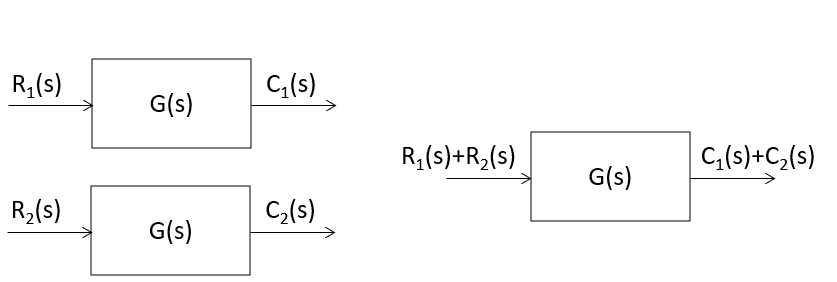

- Propocionalidad: Si $R\left(s\right)G\left(s\right)=C\left(s\right)$ entonces $\alpha R\left(s\right)G\left(s\right)=\alpha C\left(s\right)$.

            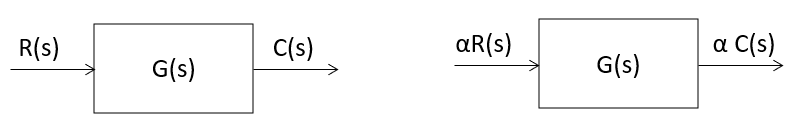

**Ejemplo propiedad aditividad:** si consideramos un resorte ideal, la relación entre la fuerza $F$ (expresada en $N$) y la deformación $x$ (expresada en $m$) que se produce es lineal y viene dada por $F=\textrm{kx}$, donde $k$ es la constante del resorte (expresada en $N/m$). De este modo, si una fuerza $F_1$ produce una deformación $x_1$, y una fuerza $F_2$ provoca una deformación $x_2$, la suma de ambas fuerzas,${\;F}_1 +F_2 \ldotp$ producirá una deformación igual a la suma de ambas deformaciones: $x_1 +x_2$. Esta propiedad de aditividad también puede interpretarse de la siguiente manera: la respuesta del resorte ante la suma de ambas fuerzas puede descomponerse en la suma de las respuestas individuales.

**Ejemplo propiedad proporcionalidad:** por otro lado, si una entrada $F$produce una deformación $x$, entonces una entrada $\alpha F$ producirá una deformación $\alpha x$, donde $\alpha$ es una constante de proporcionalidad.

La curva que resulta al mostrar graficamente la fuerza $F$ en función de la deformación $x$ es una línea recta que pasa por el origen si la relación es efectivamente lineal. Veamos gráficamente esta relación:

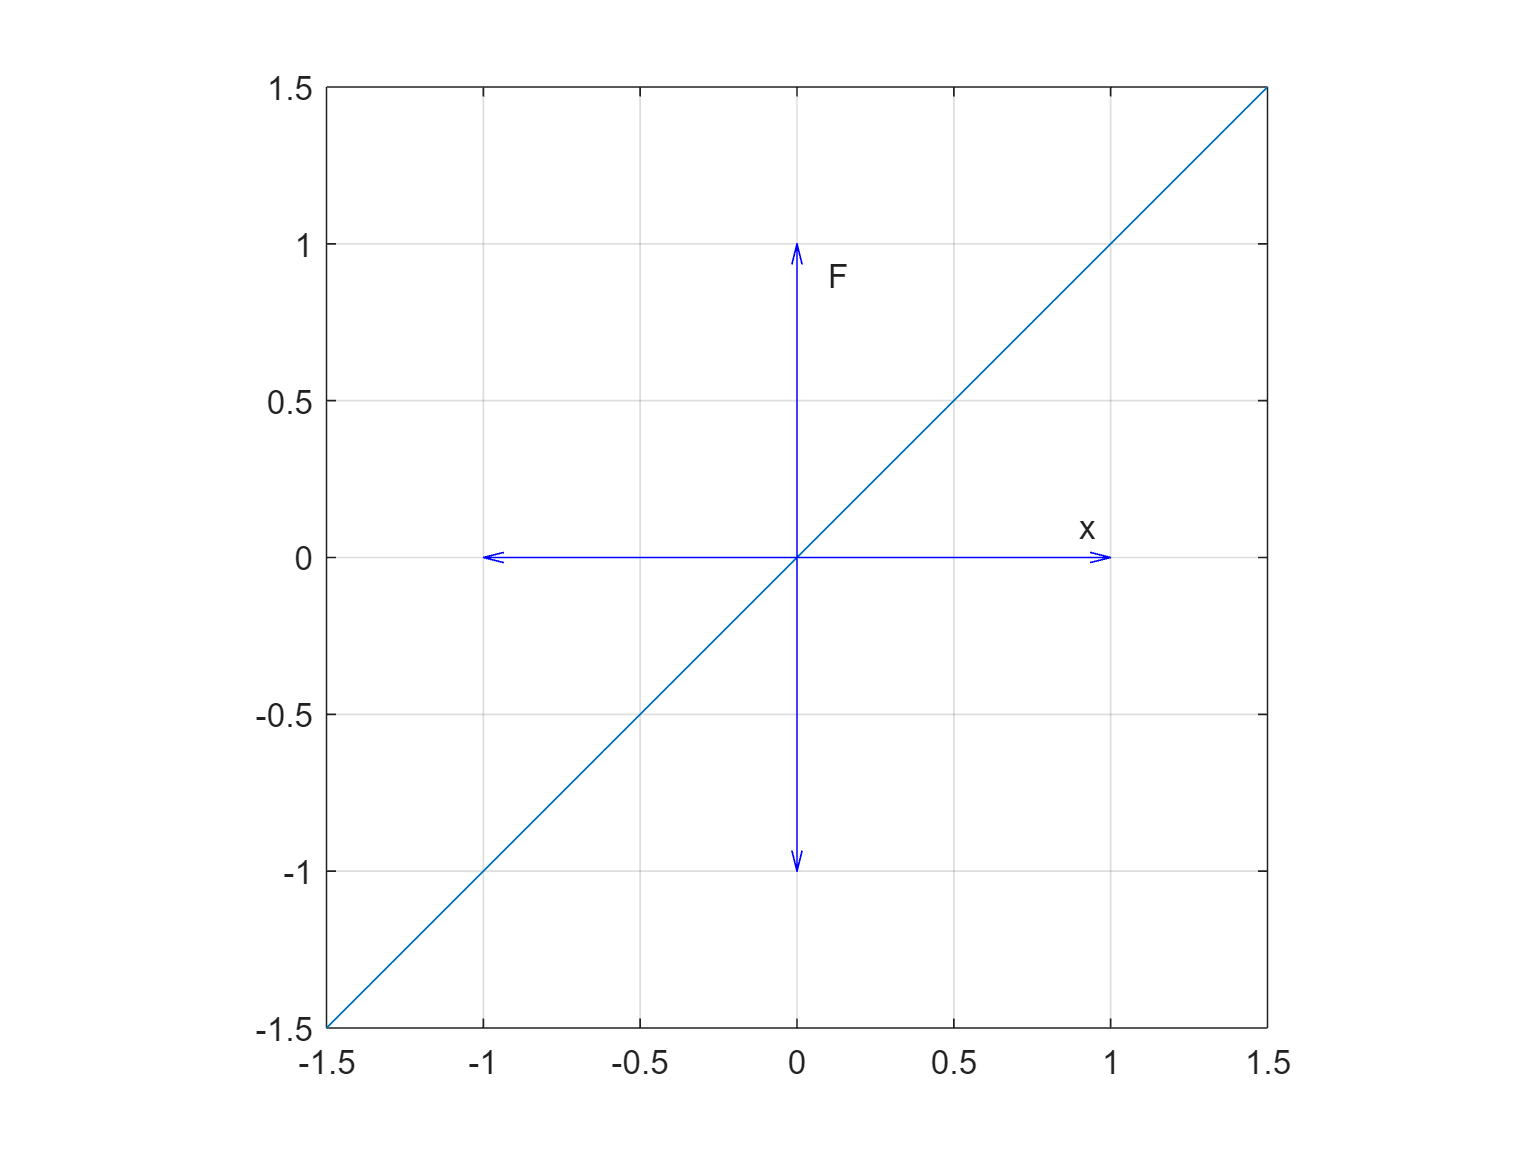

k = 1; % N/m
F=@(x) k*x;
fplot(F,[-1.5 1.5])
hold on, grid on
pbaspect([1 1 1])
quiver(0,0,0,1,0,'b'); quiver(0,0,0,-1,0,'b'); 
quiver(0,0,1,0,0,'b'); quiver(0,0,-1,0,0,'b');
text(0.1,0.9,'F'); text(0.9,0.1,'x');
hold off

Sin embargo, nos topamos con la dura realidad cuando experimentamos con resortes reales ya que, como suele ocurrir con la mayoría de componentes, no son perfectamente lineales. La siguiente figura muestra un ejemplo de relación no lineal:

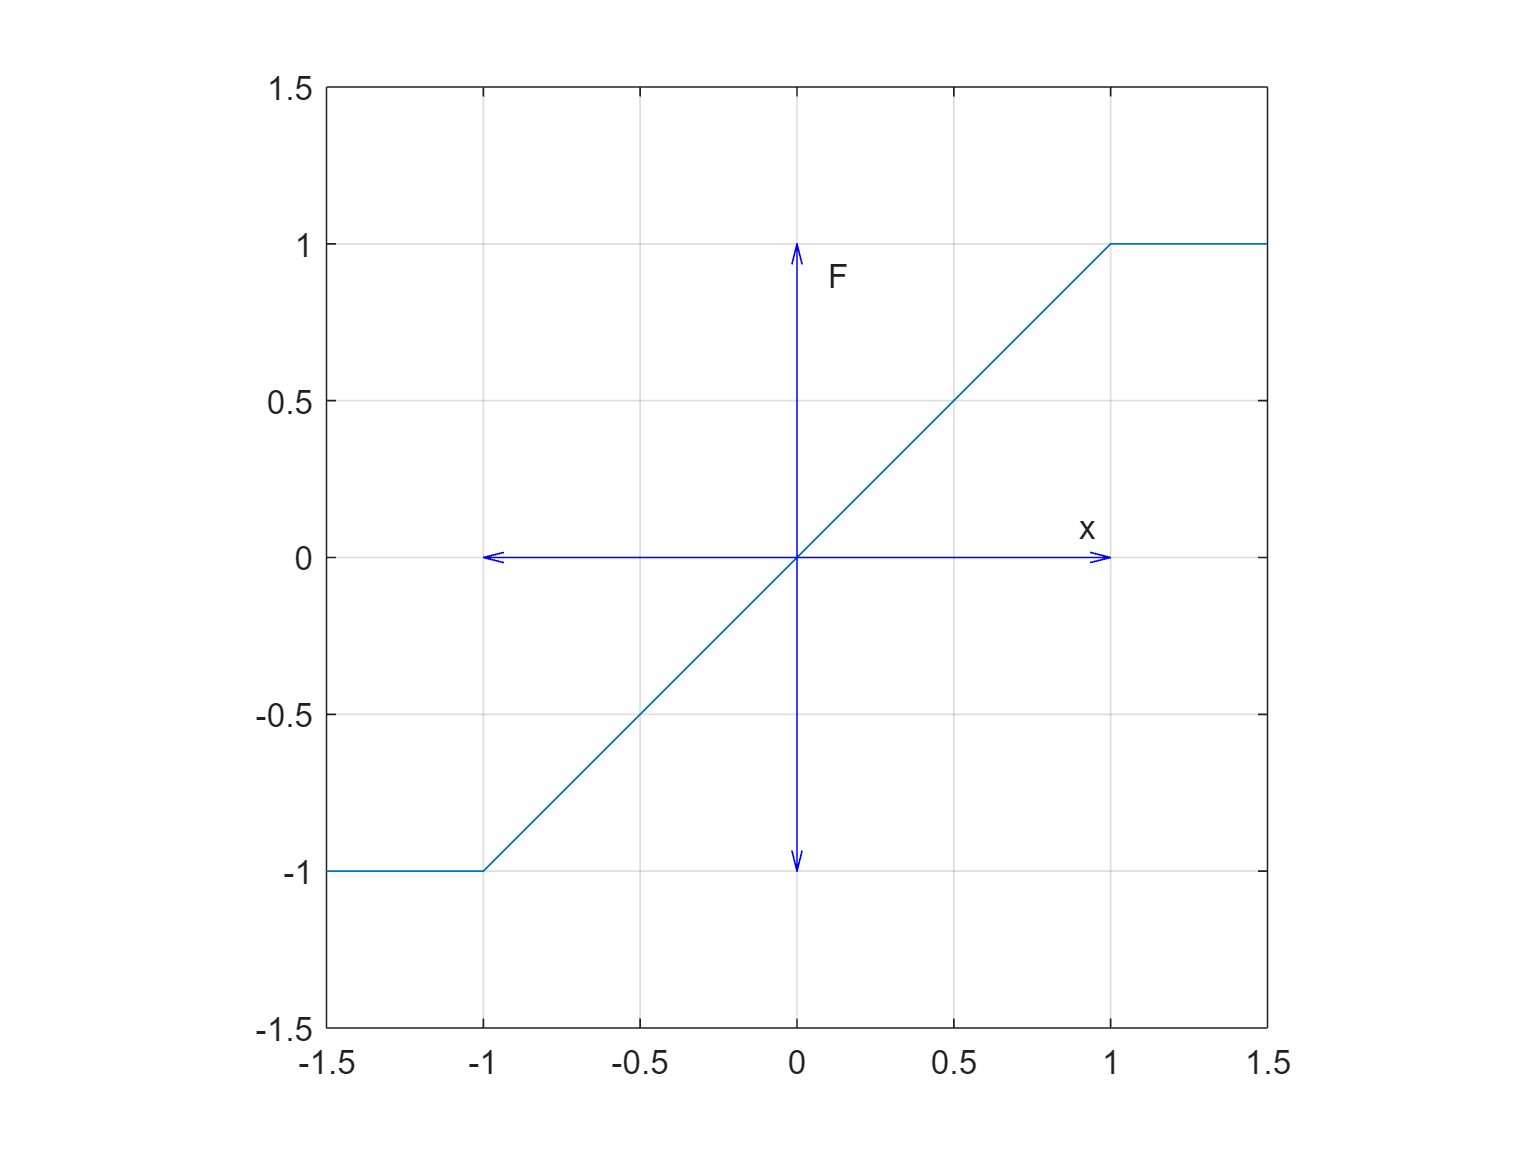

plot([-1.5,-1,1,1.5],[-1,-1,1,1])
grid on; pbaspect([1 1 1]); hold on;
xlim([-1.5 1.5]); ylim([-1.5 1.5]);
quiver(0,0,0,1,0,'b'); quiver(0,0,0,-1,0,'b'); 
quiver(0,0,1,0,0,'b'); quiver(0,0,-1,0,0,'b');
text(0.1,0.9,'F'); text(0.9,0.1,'x');
hold off

Dicha figura podría mostrar la relación entre la fuerza aplicada al resorte y su deformación cuando, llegado un punto, por más fuerza que se ejerza, no da más de sí, o bien no puede contraerse más. 

Otro ejemplo podrían ser los amortiguadores que se usan en los sistemas físicos, como la suspensión de un vehículo, los cuales pueden ser lineales para bajas velocidades del vehículo, pero que pueden volverse no lineales a altas velocidades (la fuerza de amortiguamiento puede variar con el cuadrado de la velocidad).

¡Pero no está todo perdido! Con frecuencia existe un intervalo de operación en el que la linealidad se puede suponer, y ese va a ser nuestro lugar de trabajo.

## `2. Sistemas no lineales`

Veamos las características de un sistema no lineal y la técnica de linealización con un ejemplo clásico.

### `2.1 El péndulo`

La figura siguiente representa un péndulo simple, donde:

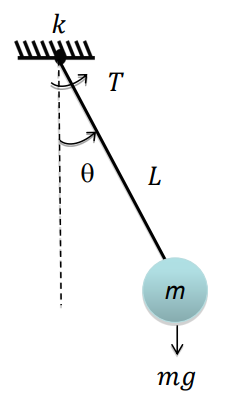

- $m$: masa de la bola (0,1kg),

- $g$: acelearción de la gravedad (9,8m/s^2),

- $L$: longitud de la barra (4m),

- $k$: coeficiente de fricción de la bisagra (0,01kg/s),

- $T$: par externo aplicado al sistema (Nm), y

- $\theta$: ángulo entre la vertical y la barra (rad).

La **dinámica** de este péndulo se describe empleando la **ley D'Alembert** (reformulación de la **segunda Ley de Newton**) para movimientos rotatorios: *la aceleración que adquiere un cuerpo es proporcional al par (torque) aplicado sobre el mismo, siendo su inercia una constante de proporcionalidad. *Sabiendo que el momento de inercia de una masa $m$ con respecto a un eje de rotación a una distancia $L$ es $J={\textrm{mL}}^2$, obtenemos:


$$\begin{array}{l}
\sum_i T_i =J\alpha \;\;\;\;\Rightarrow \;\;\;T-{\textrm{kL}}^2 \overset{\cdot }{\theta} -\textrm{mLg}\;\textrm{sen}\left(\theta \right)={\textrm{mL}}^2 \overset{\cdot \cdot }{\theta} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\overset{\cdot \cdot }{\theta} =-\frac{g}{L}\textrm{sen}\left(\theta \right)-\frac{k}{m}\overset{\cdot }{\theta} +\frac{1}{{\textrm{mL}}^2 }T
\end{array}$$


Llegados a este punto, ya podemos ver como la ecuación diferencial que modela el sistema presenta un término no lineal: $\textrm{sen}\left(\theta \right)$. La comprobación de que este no cumple el principio de superposición es trivial:

theta_1 = pi/4;
theta_2 = pi/4;
y_1 = sin(theta_1) + sin(theta_2)

y_1 = 1.4142

y_2 = sin(theta_1+theta_2)

y_2 = 1

if y_1 == y_2, disp('Sistema lineal')
else disp('Sistema NO lineal'); end

Sistema NO lineal


Como se ha comentado, las técnicas que vamos a emplear para controlar sistemas asumen que dichos sistemas tienen un comportamiento no lineal. Si, como en este caso, aparecen no linealidades, tenemos dos alternativas principales:

- Linealizar el sistema alrededor de un punto de operación. 

- Emplear técnicas de control compatibles (Gain scheduling, Lógica difusa, etc.).

En este cuaderno trabajaremos con la primera alternativa. 

### `2.2 Linealización`

Vamos a ver como podemos linealizar dicho sistema. El objetivo de la técnica de linealización no es otro que dar con un sistema lineal aproximado cuya respuesta sea similar a la del sistema no lineal original. Cuando estamos trabajando con **descripción interna** (espacio de estados), este proceso se compone de los siguientes pasos:

- Obtención de puntos de equilibrio.

- Cambio de origen a dichos puntos de equilibrio.

- Linearización de las ecuaciones de estado.

- Análisis de estabilidad de los puntos de equilibrio.

- Simulación del sistema linealizado.

- Restauración del origen inicial (permite obtener los valores numéricos del vector de estados y de la salida originales).

En el caso de estar trabajando con **descipción interna**, se puede proceder linealizando directamente la ecuación diferencial que define la dinámica del sistema aproximando en el punto de equilibrio escogido cada no linealidad. No obstante, en este cuaderno vamos a trabajar con la descricpión interna.

Empecemos por obtener los **puntos de equilibrio**: puntos alrededor de los cuales se realiza la linealización del modelo, la cúal **sólo es válida en las cercanías de estos**. Pero antes de ello, avancemos en su representación en descripción interna.

#### `Descripción interna`

Siendo la actuación (entrada) el par externo aplicado $T$, la salida el ángulo del péndulo respecto a la vertical $\theta$, y considerando como **variables de estado** el ángulo del péndulo $\theta$ y su velocidad angular $\overset{\cdot }{\theta}$:


$$\begin{array}{l}
x_1 =\theta \\
x_2 =\overset{\cdot }{\theta} 
\end{array}$$


obtenemos que la correspondiente **descripción interna** es:


$$\begin{array}{l}
\overset{\cdot }{x_1 } =x_2 \\
\overset{\cdot }{x_2 } =-\frac{g}{L}\textrm{sen}\left(x_1 \right)-\frac{k}{m}x_2 +\frac{1}{{\textrm{mL}}^2 }u\\
y=x_{\;1} 
\end{array}$$


Esta descripción interna, como podemos observar, es **no lineal.**

#### `Puntos de equilibrio`

Dado que en el punto de equilibrio el sistema no varía, o lo hace muy levemente, las derivadas temporales son cero en dicho punto, esto es, $\overset{\ldotp }{x_1 } =\overset{\ldotp }{x_2 } =0$. Vamos allá:


$$\begin{array}{l}
\overset{\ldotp }{x_1 } =0\;\;\;\Rightarrow x_{2e} =0\\
\overset{\ldotp }{x_2 } =0\;\;\;\Rightarrow u_e =\textrm{mgL}\;\textrm{sen}\left(x_{1e} \right)\\
y_e =x_{1e} 
\end{array}$$


En este caso $x_{1e}$ queda indeteraminado (depende de la entrada), pudiendo tomar cualquier valor. 

Mediante cálculo simbólico:

syms g L m k ue x1e x2e
f = [x2e; -(g/L)*sin(x1e)-(k/m)*x2e+(1/(m*L^2))*ue];
[x2e, ue] = solve(f==0, x2e, ue)

$$x2e = 0$$

$$ue = L\,g\,m\,\sin\left(\mathrm{x1e}\right)$$

ye = x1e;

Estos puntos de equilibro también son llamados** punto de operación** o **consignas**.

#### `Cambio de origen`

Con el objetivo de linealizar el sistema, es necesario **desplazar el origen de coordenadas a este punto de equilibrio**. Esta operación es similar a una traslación en el espacio Euclídeo. Para ello se definen nuevas variables de estado, actuación y salida de la siguiente forma:


$$\begin{array}{l}
\delta x_1 =x_1 -x_{1e} \\
\delta x_2 =x_2 -x_{2e} =x_2 \\
\delta u=u-u_e =u-\textrm{mgL}\;\textrm{sen}\left(x_{1e} \right)\\
\delta y=y-y_e =y-x_{1e} 
\end{array}$$


Una vez se haya resuelto la ecuación diferencial linealizada, se deshará este cambio para obtener los valores numéricos del vector de estados y de la salida originales.

#### `Linealización de las ecuaciones`

Procedemos ahora a obtener las matrices linealizadas alrededor del punto de equilbrio. Para ello se procede aproximando las matrices originales por su **desarrollo en series de Taylor**. Los términos de Taylor de orden superior a uno se descartan, y resulta la aproximación lineal de las ecuaciones de estado no lineales en el punto de equilibrio. 

Para el caso de la **ecuación de estado **(recuerdese que $f\left(x_e ,u_e \right)=0$):

$f\left(x,u\right)\approx f\left(x_e ,u_e \right)+\frac{\partial f}{\partial x}{\left|\right.}_{x_{e,} u_e } \left(x-x_e \right)$+$\frac{\partial f}{\partial u}{\left|\right.}_{x_{e,} u_e } \left(u-u_e \right)\Rightarrow \delta \overset{\ldotp }{x} \approx A\delta x+B\delta u$

donde:

 
$$f_1 =\overset{\ldotp }{x_1 } =x_2$$



$$f_2 =\overset{\ldotp }{x_2 } =-\frac{g}{L}\textrm{sen}\left(x_1 \right)-\frac{k}{m}x_2 +\frac{1}{{\textrm{mL}}^2 }u$$


Esto da como resultado las nuevas variables de estado $\delta x$ y de control $\delta u$, donde las matrices dinámica y de control resultan:


$$A={\left\lbrack \begin{array}{cc}
\frac{\partial f_1 }{\partial x_1 } & \frac{\partial f_1 }{\partial x_2 }\\
\frac{\partial f_2 }{\partial x_1 } & \frac{\partial f_2 }{\partial x_2 }
\end{array}\right\rbrack }_{x_e ,u_e } =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{g}{L}\cos \left(x_{1e} \right) & -\frac{k}{m}
\end{array}\right\rbrack$$



$$B={\left\lbrack \begin{array}{c}
\frac{\partial f_1 }{\partial u}\\
\frac{\partial f_2 }{\partial u}
\end{array}\right\rbrack }_{x_e ,u_e } =\left\lbrack \begin{array}{c}
0\\
\frac{1}{{\textrm{mL}}^2 }
\end{array}\right\rbrack$$


Por parte de la** ecuación de salida**:

$g\left(x,u\right)\approx y_e +\frac{\partial g}{\partial x}{\left|\right.}_{x_{e,} u_e } \left(x-x_e \right)$+$\frac{\partial g}{\partial u}{\left|\right.}_{x_{e,} u_e } \left(u-u_e \right)\Rightarrow \delta y\approx C\delta x+D\delta u$

con las nuevas variables de estado $\delta x$ y de control $\delta u$, donde las matrices de salida y de influencia directa son:


$$C={\left\lbrack \frac{\partial g}{\partial x_1 }\;\;\;\frac{\partial g}{\partial x_2 }\right\rbrack }_{x_e ,u_e } =\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack ,\;\;\;\;\;\;\;\;\;\;D={\left\lbrack \frac{\partial g}{\partial u}\right\rbrack }_{x_e ,u_e } =\left\lbrack 0\right\rbrack$$


Notesé que en este caso la ecuación de salida ya era lineal ($\left.y_e =x_{1e} \right)$, por lo que no hubiera sido necesario realizar ninguna operación sobre sus matrices.

Veámos como realizar los cálculos anteriores en MATLAB:

syms x1 x2 u
f = [x2; -(g/L)*sin(x1)-(k/m)*x2+(1/(m*L^2))*u];
x = [x1;x2];
% Calculamos el Jacobiano de f respecto de x
A = jacobian(f,x);
% Y para la matriz de control con respecto de u
B = jacobian(f,u);
% Evaluamos en x=xe y u=ue
x1=x1e;
x2=x2e;
u=ue;
A = eval(A)

$$A = \left(\begin{array}{cc} 0 & 1\\ -\frac{g\,\cos\left(\mathrm{x1e}\right)}{L} & -\frac{k}{m} \end{array}\right)$$

B = eval(B)

$$B = \left(\begin{array}{c} 0\\ \frac{1}{L^{2}\,m} \end{array}\right)$$

C = [1 0];
D = 0;

#### `Llevando las cosas a la tierra: dándole valores a los parámetros del problema`

Supongamos que se quiere someter el sistema a una actuación $u=u_e$ para llevarlo desde un punto inicial en equilibrio a 90º ($x_1 =\pi /2,x_2 =0$) hasta uno final a 60º ($x_1 =\pi /3,x_2 =0$) . En este caso, el punto de equilibrio será:

                
$$\begin{array}{l}
x_{1e} =\pi /3=1\ldotp 0472\;\textrm{rad}\\
x_{2e} =0\;\textrm{rad}/s\\
u_e =\textrm{mgL}\;\textrm{sen}\left(x_{1e} \right)=3\ldotp 3948\;N\cdot m\\
y_e =1\ldotp 0472\;\textrm{rad}
\end{array}$$


De este modo, el origen se desplaza a este punto de equilibrio:

                
$$\begin{array}{l}
\delta x_1 =x_1 -x_{1e} =x_1 -1\ldotp 0472\\
\delta x_2 =x_2 -x_{2e} =x_2 \\
\delta u=u-u_e =u-\textrm{mgL}\;\textrm{sen}\left(x_{1e} \right)=u-3\ldotp 3948\\
\delta y=y-y_e =y-x_{1e} =y-1\ldotp 0472
\end{array}$$


y el estado inicial pasa a ser:                $\begin{array}{l}
\delta x_1 \left(0\right)=x_1 \left(0\right)-1\ldotp 0472=\pi /2-1\ldotp 0472=0\ldotp 5236\\
\delta x_2 \left(0\right)=x_2 \left(0\right)=0
\end{array}$

Las matrices linealizadas para este punto de equilibro en concreto son:

                
$$A=\left\lbrack \begin{array}{cc}
0 & 1\\
-1\ldotp 225 & -0\ldotp 1
\end{array}\right\rbrack \;\;\;\;\;\;\;\;B=\left\lbrack \begin{array}{c}
0\\
0\ldotp 625
\end{array}\right\rbrack$$


               
$$\;C=\left\lbrack \begin{array}{cc}
1 & 0
\end{array}\right\rbrack \;\;\;\;\;\;\;D=0$$


y, finalmente, el sistema linearizado alrededor de este punto:

                
$$\begin{array}{l}
\delta \overset{\ldotp }{x_1 } =\delta x_2 \\
\delta \overset{\ldotp }{x_2 } =-1\ldotp 225\delta x_1 -0\ldotp 1\delta x_2 +0\ldotp 625\delta u\\
\delta y=\delta x_1 
\end{array}$$


En MATLAB:

% Constantes
g = 9.8;
L = 4;
m = 0.1;
k = 0.01;
% Punto de equilibrio
x1e = pi/3;
x2e = eval(x2e);
ue = eval(ue);
ye = eval(ye);
% Matrices liealizadas
A = eval(A)

A =          0    1.0000
   -1.2250   -0.1000


B = eval(B)

B =          0
    0.6250


#### `Estabilidad de los puntos de equilibrio`

Vamos a comprobar si el sistema es estable:

lambda = eig(A)

lambda =   -0.0500 + 1.1057i
  -0.0500 - 1.1057i


Como podemos ver, la parte real de los autovalores (o polos) complejos es negativa, por lo que se puede determinar que el sistema es **asintóticamente estable** alrededor del punto de equilibrio.

### `2.3 Simulación del sistema linealizado `

Vamos a ver ahora como realizar una simulación del sistema ya linealizado empleando MATLAB. Para ello vamos a recurrir a una serie de funciones auxiliares.

#### `Comando lsim`

Este comando ya nos suena de cuadernos anteriores: simula la respuesta temporal de un sistema dinámico ante una determinada entrada. Su sintaxis es:

`[`$\delta$`y,t,`$\delta$`x]=lsim(G,`$\delta$`u,t,`$\delta$`x0)`

donde:

- $\delta$`y`: respuesta temporal del sistema linealizado para cada uno de los valores del vector `t.`

- `t`: vector de tiempos utilizado para la simulación 

- $\delta$`x`: variables de estado linealizadas calculadas para cada uno de los valores del vector `t.` 

- `G`: sistema dinámico a simular. Para el caso de una descripción interna viene dado por `G=ss(A,B,C,D)`. 

- $\delta$`u`: actuación, con el mismo número de elementos que el vector `t.` 

- $\delta$`x0`: vector de condiciones iniciales.

#### `Comando linspace`

Genera un vector con N valores linealmente espaciados entre un valor `Tinicial` y un valor `Tfinal`. Se utilizará para generar el vector de tiempos `t`. Su sintaxis es:

`t = linspace(Tinicial,Tfinal,N)`

donde:

- `Tinicial:` tiempo inicial en el que comenzar a generar valores.

- `Tfinal:` tiempo final en el que parar de generar valores.

- `N: `número de puntos intermedios.

Veamos entonces como simular el modelo linealizado empleando estas funciones:

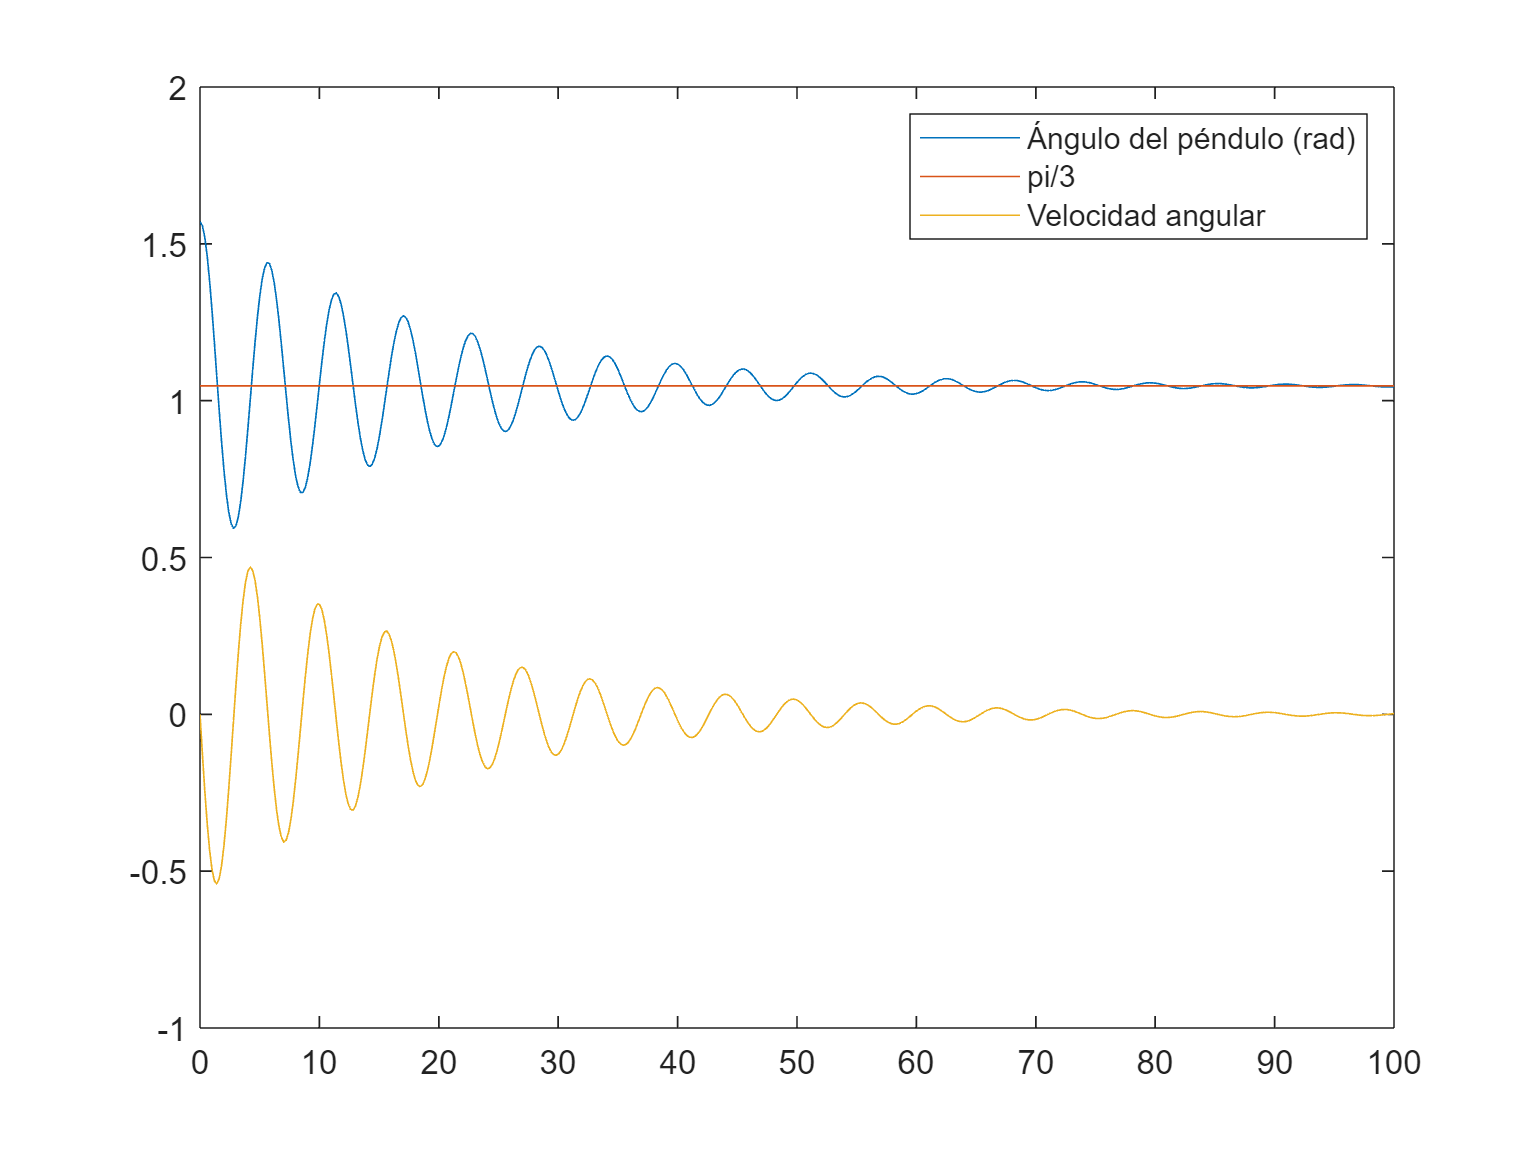

X0 = [pi/2 0];      % Condiciones iniciales(es de donde parte el pendulo)
Tf = 100;           % Tiempo de simulación
N = 500;            % Número de puntos intermedios
delta_u = zeros(1,N); % Actuación( actuación nula pq independientemente de cual sea el punto de equilibrio)
t=linspace(0,Tf,N); % Vector de tiempos
delta_x0 = X0-[x1e x2e];     % Condición inicial para el punto de equilibrio

G=ss(A,B,C,D);      % Matrices linealizadas

% Simulamos la respuesta del sistema en los instantes de tiempo t con entrada delta_u
[delta_y,t,delta_x] = lsim(G,delta_u,t,delta_x0); 

Xlin = delta_x+[x1e x2e];    % Se deshace el cambio para obtener X
Ylin = delta_y+ye;           % Se deshace el cambio para obtener Y

% Comprobemos la respuesta
plot(t,Ylin); hold on
plot([0,100],[pi/3,pi/3]);
plot(t,Xlin(:,2)); 
hold off
legend('Ángulo del péndulo (rad)','pi/3','Velocidad angular')

Notesé que $u=u_e \;\Rightarrow \delta u=0$, es decir, estamos ante una ecuación de estado con actuación nula, por lo que en este caso concreto se puede resolver también mediante la matriz exponencial: $\delta x\left(t\right)=e^{\textrm{At}} \cdot \delta \textrm{x0}$. La interpretación de esto es que, una vez estamos en el punto de equilibrio objetivo, la variación de actuación ha de ser 0 o cercana a 0 para mantenernos en él.

#### `El magnífico comando ode23`

Este comando nos permite resolver un sistema de ecuaciones diferenciales de primer orden $\overset{\ldotp }{x} =f\left(t,x\right)$ utilizando métodos de Runge-Kutta con fórmulas de segundo y tercer orden. Su sintaxis es:

`[tout, xout]=ode23(odefun,tspan,X0)`

donde:

- `tout`: vector de tiempos en los que se ha evaluado la solución.

- `xout`: soluciones de la ecuación diferencial.

- `odefun`: sistema de funciones `f(t,x)` a resolver, especificadas como un vector de funciones tipo `function_handle` de Matlab 

- `tspan`: intervalo de integración, especificado como un vector con formato `[t0 tfinal]. `

- `X0`: condiciones iniciales, especificadas como un vector.

De este modo podemos obtener la solución al **sistema original no lineal**:

U = ue;             % Par aplicado al péndulo
dxdt = @(t,x) [x(2); -g/L*sin(x(1))-k/m*x(2)+1/(m*L^2)*U];
[tout, Xorig] = ode23(dxdt,[0 Tf],X0);
Yorig = Xorig(:,1);

### `2.4 Comparación de resultados`

En la sección aterior hemos obtenido la respuesta del sistema de ecuaciones original (empleando `ode23`), así como el linealizado (mediante `linspace` y `lsim`). Ahora vamos a representar gráficamente e interpretar los resultados obtenidos.

Para ello se va a representar primero la respuesta temporal, y después pasaremos a comentar representación en el plano de estados (también llamado plano de fase), cuyas coordenadas son las dos variables de estado definidas.

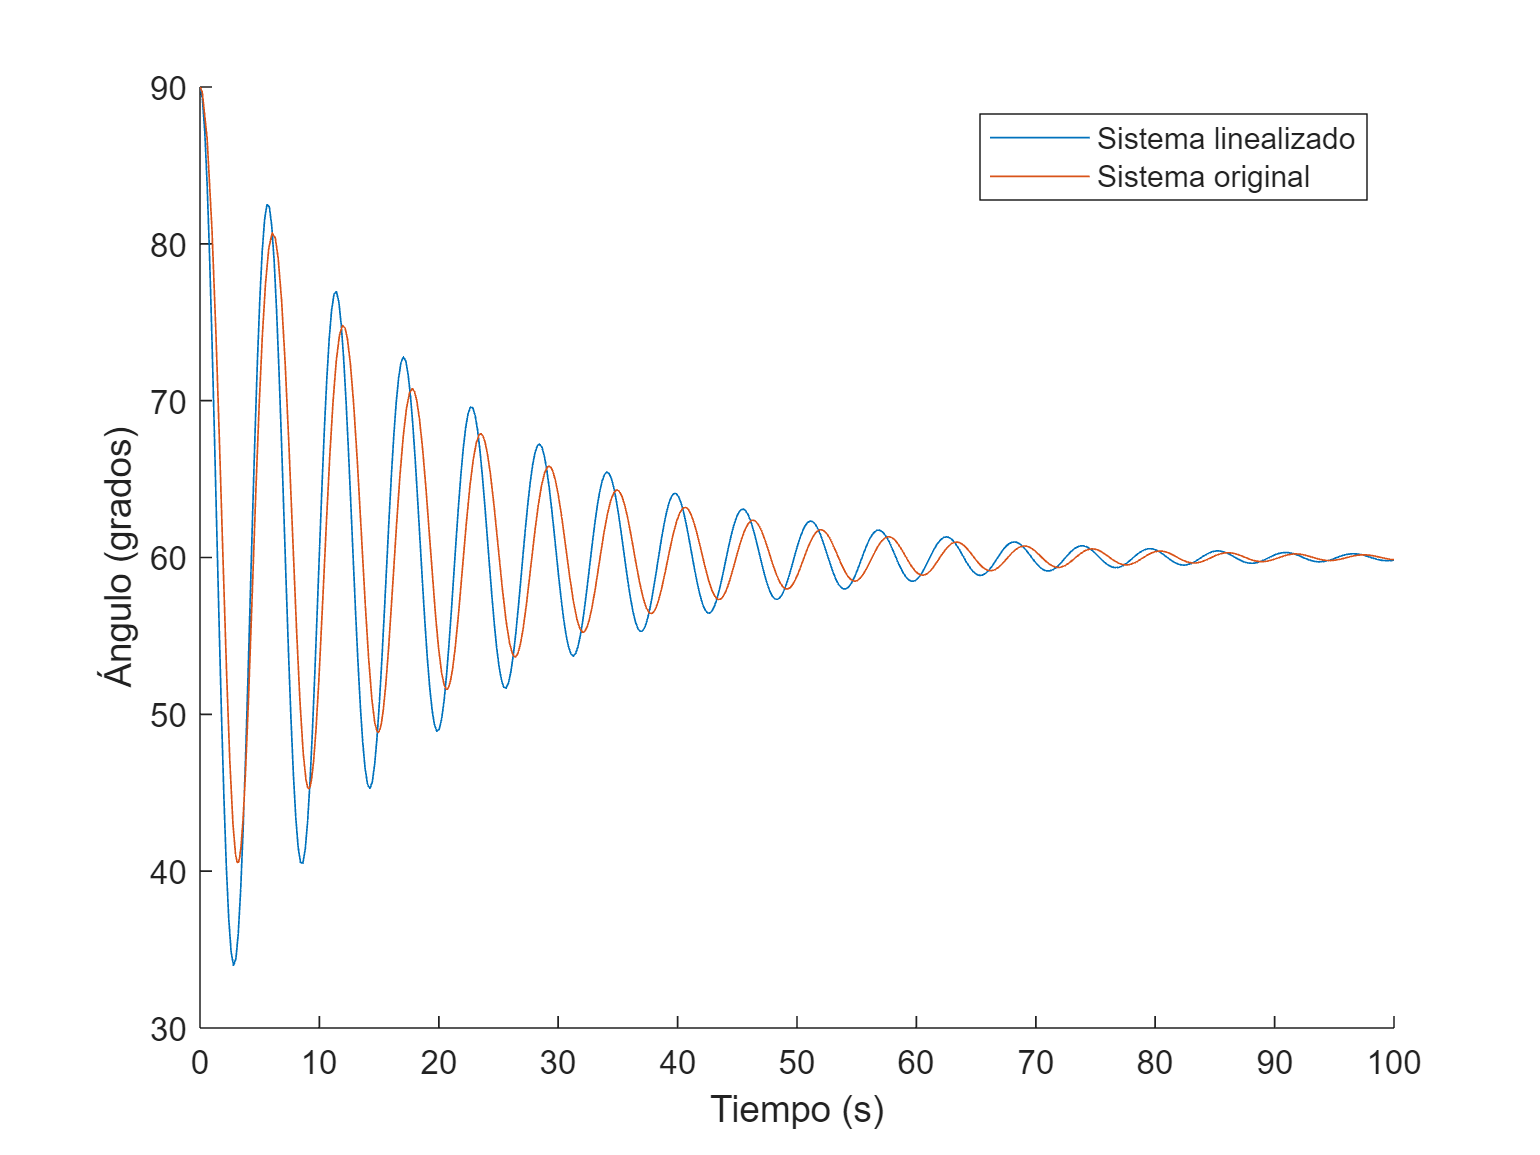

% Representación de la respuesta temporal
figure; hold on
plot(t,Ylin(:,1)*180/pi)
plot(tout,Yorig*180/pi)
hold off
xlabel('Tiempo (s)')
ylabel('Ángulo (grados)')
legend('Sistema linealizado','Sistema original')

Se observa que el péndulo parte de 90º y su oscilación se va amortiguando a medida que transcurre el tiempo, tendiendo a 60º, en concordancia al punto de equilibrio considerado. Las amplitudes de las oscilaciones obtenidas con el sistema linealizado son algo mayores que las del sistema original, presentando también cierto adelanto respecto a estas últimas.

Vamos ahora con la representación en el plano de estados:

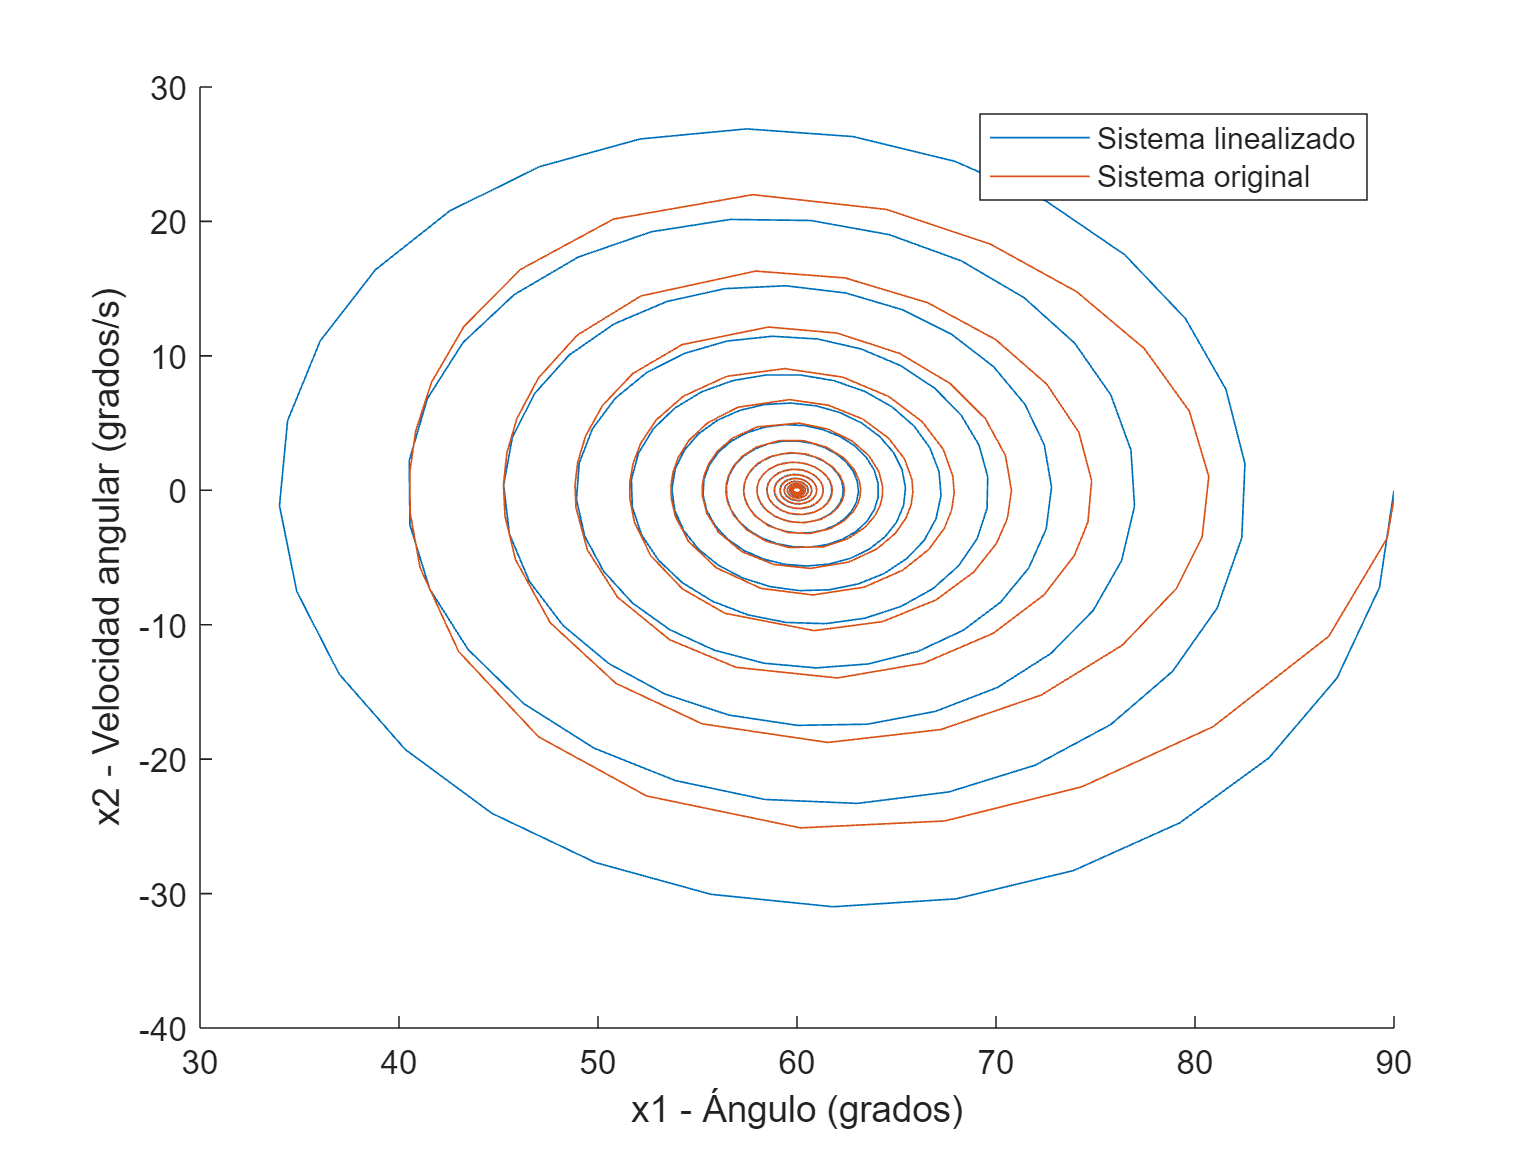

% Representación en el plano de estados
figure; hold on
plot(Xlin(:,1)*180/pi,Xlin(:,2)*180/pi)
plot(Xorig(:,1)*180/pi,Xorig(:,2)*180/pi)
hold off
xlabel('x1 - Ángulo (grados)')
ylabel('x2 - Velocidad angular (grados/s)')
legend('Sistema linealizado','Sistema original')

En esta representación se aprecia con mayor claridad la diferencia entre el sistema linealizado y el sistema original en los instantes iniciales. El péndulo parte de 90º con velocidad angular nula y oscila hasta alcanzar su posición de equilibrio a 60º y velocidad angular también nula. 

A medida que la amplitud de las oscilaciones decrece, también lo hace el error absoluto entre la respuesta proporcionada por el sistema linealizado y el sistema original.

Hemos aprendido un montón de cosas, ¿verdad? ¡Pongámoslas en práctica!

### `Resumen`

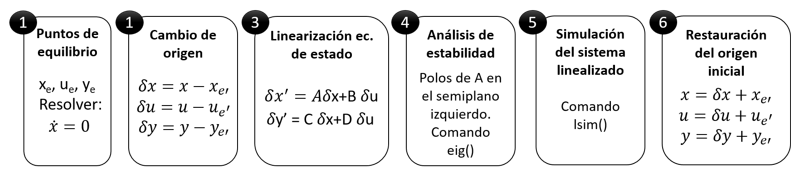

**Tarea 1:** Las ecuaciones de Volterra-Lotka se emplean para describir el modelo predador-presa de un proceso biológico:

                
$$\begin{array}{l}
\overset{\ldotp }{x_1 } =-x_1 +x_1 x_2 \\
\overset{\ldotp }{x_2 } =x_2 -x_1 x_2 
\end{array}$$


donde $x_1$ representa la población de predadores y $x_2$ la de presas. Considera que la salida del sistema es $y=x_1$. Se pide: 

        1. Calcular todos los puntos de equilibrio, tanto analíticamente como empleando cálculo simbólico en Matlab. 

% Tu código aquí
syms x1e x2e 
f = [-x1e + x1e*x2e;x2e - x1e*x2e];
[x1e,x2e] = solve(f==0,x1e,x2e)

$$x1e = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

$$x2e = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

`Resultado esperado:`

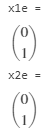

        2. Linealizar las ecuaciones de estado alrededor de cada punto de equilibrio. 

% Tu código aquí
% Punto de equilibrio x1e=0, x2e=0
syms x1 x2 y1 
f = [-x1 + x1*x2;x2 - x1*x2];
x = [x1;x2];
y = [y1];
A = jacobian (f,x);
B = jacobian(f,y);
C = [1 0];
D = 0;
y1 = 0;
x1 = 0; 
x2 = 0;
A = eval(A);
B = eval(B);
eq1 = ss(A,B,C,D)

eq1 =
 
  A = 
       x1  x2
   x1  -1   0
   x2   0   1
 
  B = 
       u1
   x1   0
   x2   0
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


% Punto de equilibrio x1e=1, x2e=1
syms x1 x2 y1 
f = [-x1 + x1*x2;x2 - x1*x2];
x = [x1;x2];
y = [y1];
A = jacobian (f,x);
B = jacobian(f,y);
C = [1 0];
D = 0;
y1 = 1;
x1 = 1; 
x2 = 1;
A = eval(A);
B = eval(B);
eq2 = ss(A,B,C,D)

eq2 =
 
  A = 
       x1  x2
   x1   0   1
   x2  -1   0
 
  B = 
       u1
   x1   0
   x2   0
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


*Resultados esperados:*

*Primer punto de equilibrio:*

 

`Segundo punto de equilibrio:`

 

        3. Estudiar la estabilidad de los puntos de equilibrio. 

% Tu código aquí
A1 = [-1 0; 0 1];
A2 = [0 1;-1 0];

fprintf('Los polos del primer punto de equilibrio: ')

Los polos del primer punto de equilibrio: 

lambda1 = eig(A1)

lambda1 =     -1
     1


fprintf('Los polos del segundo punto de equilibrio: ')

Los polos del segundo punto de equilibrio: 

lambda2 = eig(A2)

lambda2 =    0.0000 + 1.0000i
   0.0000 - 1.0000i


`Resultado esperado:`

        4. Comparar sobre el plano de estados la simulación de los procesos no lineal y linealizados cuando se parte de $x_1 =2$ y $x_2 =1$. Realizar las simulaciones en el intervalo de tiempo `t=[0,10]`.

% Tu código aquí
% Sistema no linealizado (Pista: Utiliza ode23)
syms x1 x2
x = [x1;x2];
t = linspace(0,10,5);
dxdt = @(t,x) [-x(1) + x(1)*x(2);x(2)-x(1)*x(2)];
[tout,Xorig]=ode23(dxdt,[0 10],[2 1]);
X1ode=Xorig(:,1);
X2ode=Xorig(:,2);



% Sistema linealizado (Pista: Utiliza linspace y lsim)
x0=[2 1];
t=linspace(0 ,10);
entrada=zeros(1,100);
incremento_x0=x0-[1 1];
[delta_y,t,delta_x]=lsim(eq2,entrada,t,incremento_x0);
X_lin=delta_x+[1 1];
Y_lin=delta_y;
xlineal_1=X_lin(:,1);
xlineal_2=X_lin(:,2);


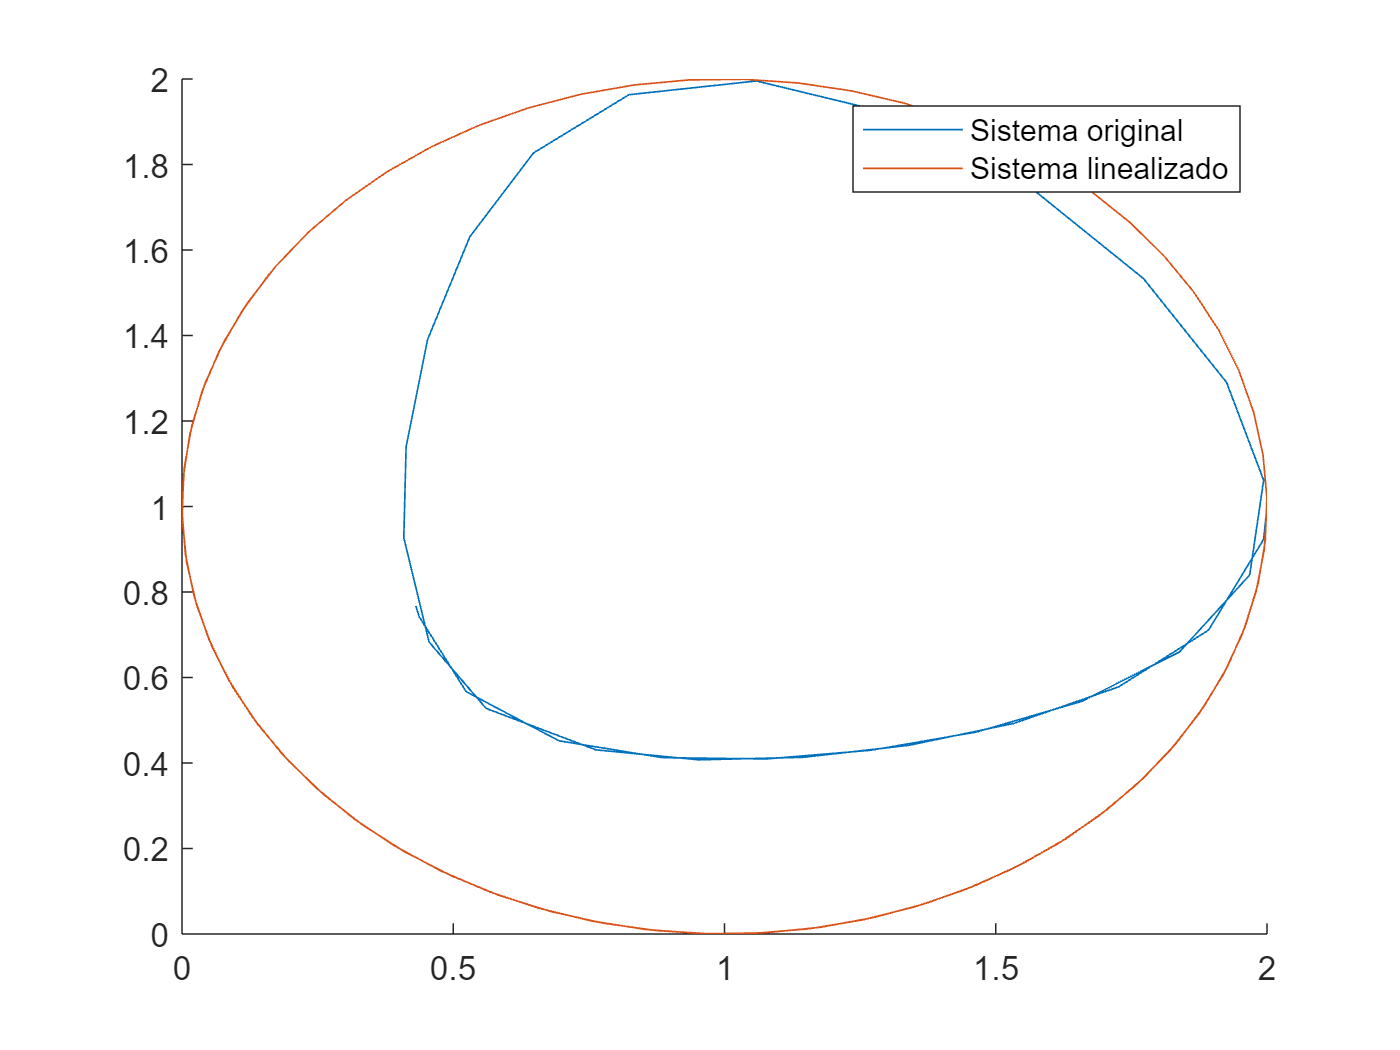

% Compara ambas simulaciones
figure;
hold on
plot(X1ode,X2ode)
plot(xlineal_1,xlineal_2)
legend('Sistema original','Sistema linealizado')
hold off

`Resultado esperado:`

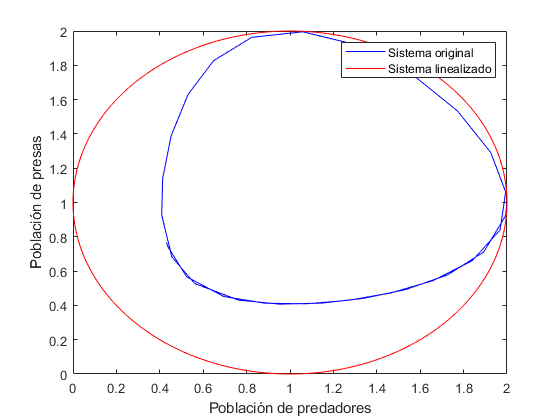

**Tarea 2:** Supóngase el sistema mecánico de traslación de la siguiente figura:

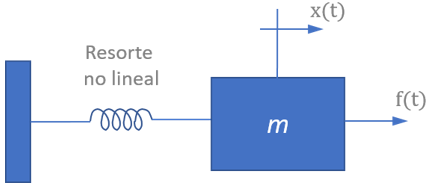

donde:

- $f\left(t\right)$ reprsenta la fuerza aplicada a la masa $m$,

- $x\left(\left(t\right)\right.$ modela el desplazamiento horizontal de dicha masa,

- la relación entre la fuerza aplicada al resorte y su desplazamiento es $\left.f_r \left(t\right)\right)=2x_s^2 \left(t\right)$ (no lineal).

La dinámica del sistema viene definida por la ecuación diferencial:

        
$$f\left(t\right)=m\frac{\partial^2 x\left(t\right)}{\partial t}+{\textrm{kx}}^2 \left(t\right)$$


Se pide:

          **1.** Obtener la descripción interna de dicho sistema a mano, teniendo en cuenta que la entrada al mismo es la fuerza aplicada $y\left(t\right)$, y la salida es el desplazamiento que experimenta la masa $x\left(t\right)$. Los parámetros del problema son $k=2$ y $m=1\textrm{Kg}$.

`Resultado esperado:`


$$\begin{array}{l}
x_1 =x\\
x_{\;2} =x^{\prime } \;\;\;\;\;\;\;\;
\end{array}$$

$$\begin{array}{l}
{x_1 }^{\prime } =x^{\prime } =x_2 \\
{x_2 }^{\prime } =u\left(t\right)-2x_1^2 
\end{array}$$


*Podemos comprobar como existe una no linealidad, por lo que no podremos definir aún las matrices A, B, C y D.*

          **2.** Obtener el punto de equilibrio del sistema, tanto a mano como con cálculo simbólico, suponiendo que se va a aplicar una fuerza constante de $10N$ ($u_e =10$).

% Tu código aquí
k = 2;
m = 1;
syms x1e x2e ye
f = [x2e; 10 - 2*x1e^2];
[x1e_sol,x2e_sol]=solve(f==0,x1e,x2e)

$$x1e\_sol = \left(\begin{array}{c} \sqrt{5}\\ -\sqrt{5} \end{array}\right)$$

$$x2e\_sol = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

ye = x1e

$$ye = \mathrm{x1e}$$

`Resultado esperado:`

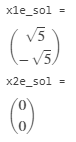

        **3.** Linealizar las ecuaciones de estado, tanto a mano como empleando cálculo simbólico.

% Tu código aquí
syms x1 x2 u 
x = [x1;x2];
f = [x2; u - 2*x1^2];
A = jacobian(f,x);
B = jacobian(f,u);
C = [1 0]

C =      1     0


D = 0

D = 0

x1 = x1e;
x2 = x2e;
u = 10;
A = eval(A)

$$A = \left(\begin{array}{cc} 0 & 1\\ -4\,\mathrm{x1e} & 0 \end{array}\right)$$

B = eval(B)

B =      0
     1


C

C =      1     0


D

D = 0

`Resultado esperado:`

        **4.** Comprobar la estabilidad del sistema en los dos puntos de equilibrio, y definir las matrices A, B, C y D con las que trabajar.

% Tu código aquí
% Para el primer punto de equilibrio, x1e = sqrt(5), x2e = 0;
A1=[0 1;-4*sqrt(5) 0];
lambda1= eig(A1)

lambda1 =    0.0000 + 2.9907i
   0.0000 - 2.9907i


% Para el segundo punto de equilibrio, x1e = -sqrt(5), x2e = 0;
A2=[0 1;-4*-sqrt(5) 0];
lambda2= eig(A2)

lambda2 =     2.9907
   -2.9907


% Definición del punto de equilibrio y matrices A, B, C y D
sist=ss(A1,B,C,D)

sist =
 
  A = 
           x1      x2
   x1       0       1
   x2  -8.944       0
 
  B = 
       u1
   x1   0
   x2   0
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


`Resultado esperado:`

*Se puede comprobar como para el punto de equilibrio *$\left\lbrack x_{1e} ,x_{2e} \right\rbrack =\left\lbrack -\sqrt{5},0\right\rbrack$ *el sistema es inestabl, mientras que para *$\left\lbrack x_{1e} ,x_{2e} \right\rbrack =\left\lbrack \sqrt{5},0\right\rbrack$* el sistema se encuentra en el límite de estabilidad. Esto va a tener sus consecuencias, como veremos al analizar la respuesta del sistema*.

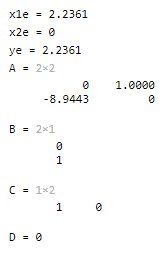

          **5.** Simular la respuesta del sistema linealizado, suponiendo que parte de un desplazamiento inicial de $1m$ y estando parado (esto es, $\left.x_0 =\left\lbrack x_{10} ,x_{20} \right\rbrack =\left\lbrack 1,0\right\rbrack \right)$. Realizar la simulación para el intervalo de tiempo $t=\left\lbrack 0,10\right\rbrack$ tomando 400 puntos intermedios.

*Pista: usa *`linspace`* y *`lsim`*.*

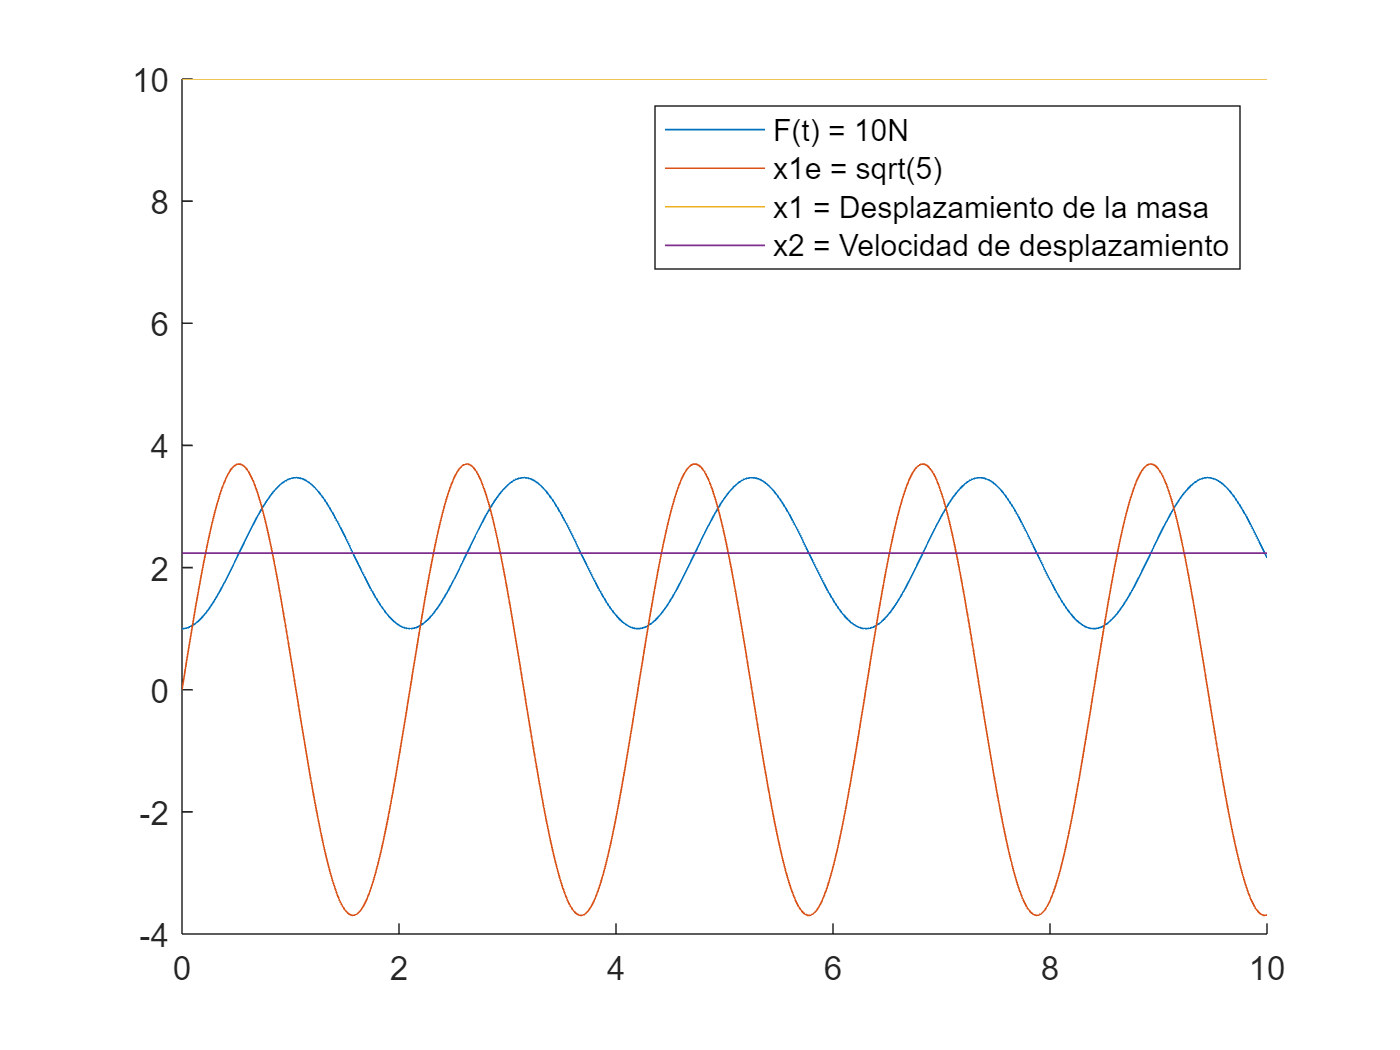

% Tu código aquí
x0=[1 0];
Tf=10;
N=400;
delta_u=zeros(1,N);
t=linspace(0,Tf,N);
delta_x0=x0-[sqrt(5) 0];
[delta_y,t,delta_x]=lsim(sist,delta_u,t,delta_x0);
Xlin=delta_x+[sqrt(5) 0];
x1lin=Xlin(:,1);
x2lin=Xlin(:,2);
figure
hold on
plot(t,x1lin);
plot(t,x2lin);
plot(t,10*ones(1,N))
plot(t,sqrt(5)*ones(1,N))
legend('F(t) = 10N','x1e = sqrt(5)','x1 = Desplazamiento de la masa','x2 = Velocidad de desplazamiento')
hold off

`Resultado esperado:`

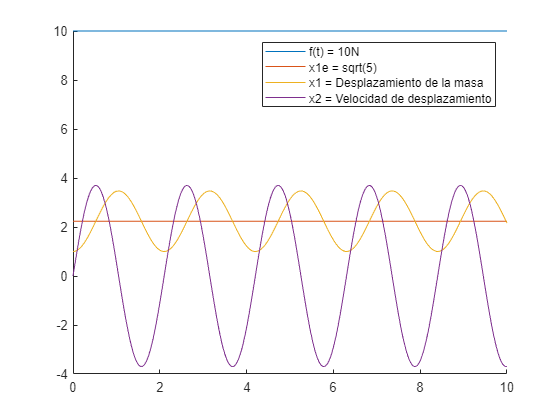

         ** 6.** Comparar sobre el plano de estados la simulación de los procesos no lineal y linealizados. 

*Pista: usa *`ode23`* para simular el sistema original.*

% Tu código aquí
% Simulación del sistema original
dxdt=@(t,x) [x(2);10-2*x(1)^2];
[tout,Xorig]=ode23(dxdt,[0,Tf],x0);
Yorig=Xorig(:,1);

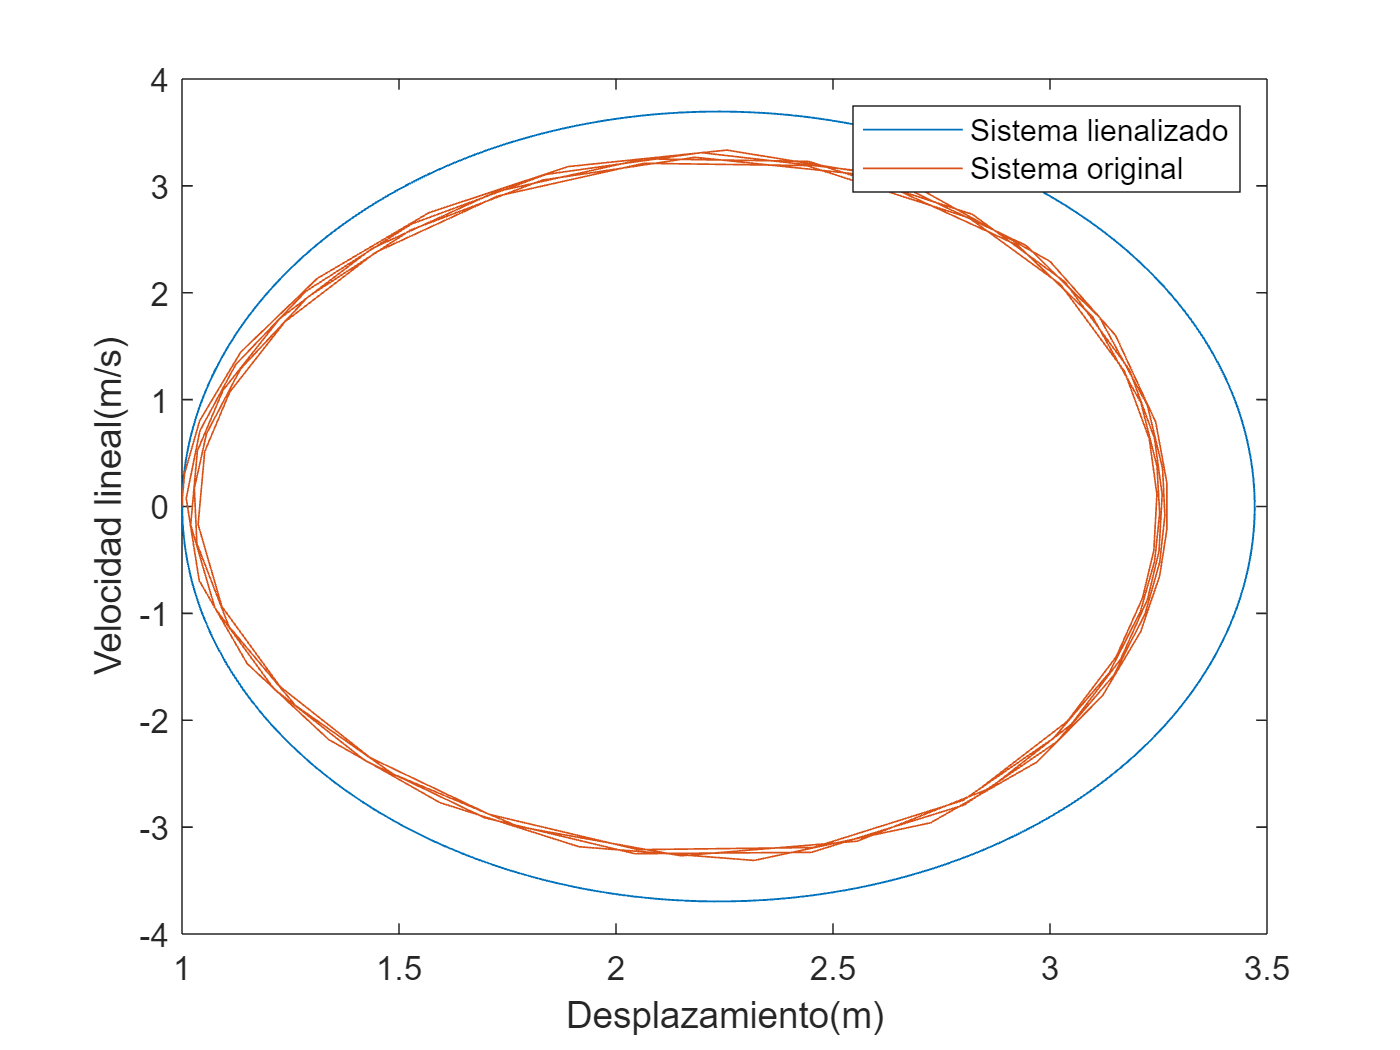

% Representación en el plano de estados
plot(x1lin,x2lin)
hold on
plot(Xorig(:,1),Xorig(:,2))
legend('Sistema lienalizado', 'Sistema original')
xlabel('Desplazamiento(m)')
ylabel('Velocidad lineal(m/s)')
hold off

`Resultado esperado:`